# 从.o文件获取剂量率图

## 1. 预设参数

fileName = 'n0.o';
particleType = 'neutron';% 仅用于图标题
scale_fs = -9.8:0.4:49.8;
scale_c  = -14.8:0.4:14.8;
n_fs = length(scale_fs);
n_c  = 0.5*(1+length(scale_c));
currentuA = 20;% uA 工作电流，仅用于图标题
dis=[0,0.5,1,2.5,5,10,100]; % 等高线位置
doseMap = zeros(n_c,n_fs);
doseMap_err = zeros(n_c,n_fs);

## 2. 获取数据

fid = fopen(fileName,'r');
i = 1;
while 1
    dataline = fgetl(fid);
    if strncmp(dataline,' s axis',7)
        fgetl(fid); % 跳过一行
        data = str2num(fgetl(fid));
        doseMap(i) = data(1);
        doseMap_err(i) = data(2);
        i = i+1;
        if i > n_c*n_fs
            break;
        end
    end
end

doseMap = doseMap*currentuA*1e-6/(1.6e-19)*1e4;% 每秒电子数*rem转uSv
doseMap = [flipud(doseMap);doseMap(2:end,:)];
doseMap_err = [flipud(doseMap_err);doseMap_err(2:end,:)];

## 3. 数据可视化

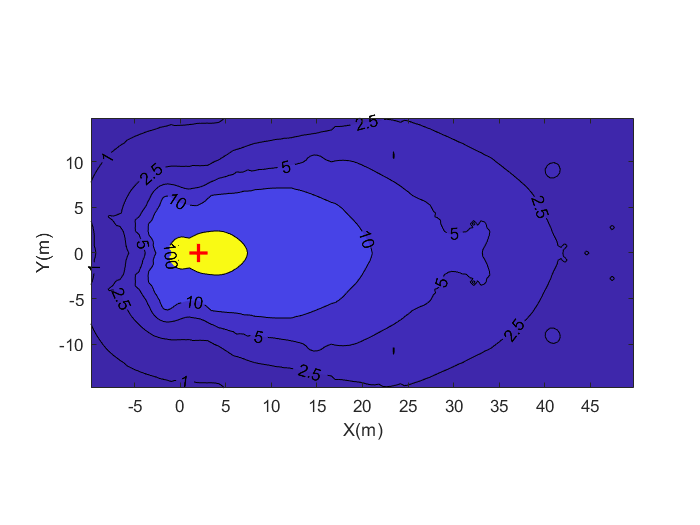

figure;
[C,h] = contourf(scale_fs,scale_c,doseMap,dis);
hold on;
clabel(C,h,'FontSize',10,'Color','k');
xlabel('X(m)');ylabel('Y(m)');
%title(['Simulated ',particleType,' does rate(\muSv/hr) @ ',num2str(currentuA),'\muA']);
axis equal;
thisWidth = 2;
thisLength = 1;
plot([2-thisLength, 2+thisLength],[0, 0],'r-','LineWidth',thisWidth);
plot([2, 2],[0-thisLength, 0+thisLength],'r-','LineWidth',thisWidth)
hold off;

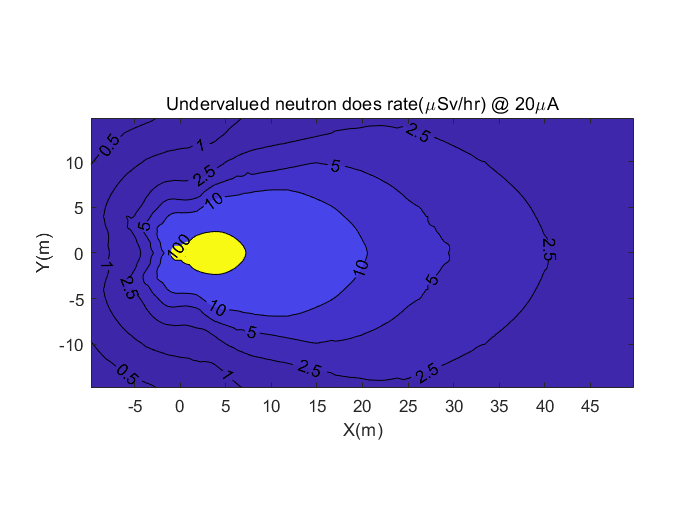


figure;
[C,h] = contourf(scale_fs,scale_c,doseMap-doseMap.*doseMap_err,dis);
clabel(C,h,'FontSize',10,'Color','k');
xlabel('X(m)');ylabel('Y(m)');
title(['Undervalued ',particleType,' does rate(\muSv/hr) @ ',num2str(currentuA),'\muA']);
axis equal;

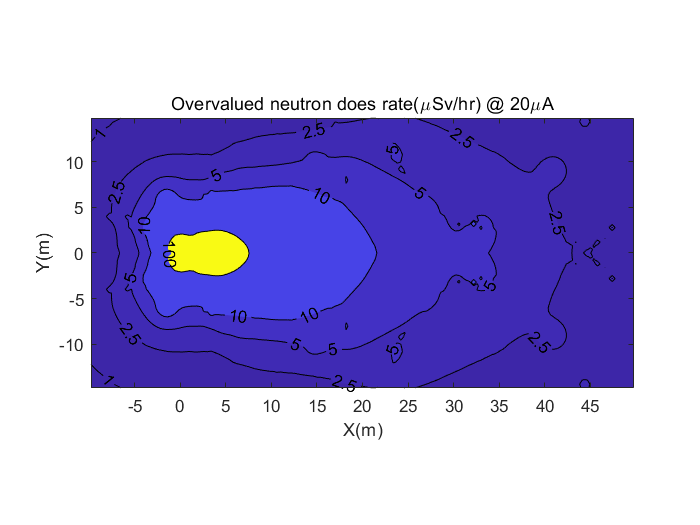

figure;
[C,h] = contourf(scale_fs,scale_c,doseMap+doseMap.*doseMap_err,dis);
clabel(C,h,'FontSize',10,'Color','k');
xlabel('X(m)');ylabel('Y(m)');
title(['Overvalued ',particleType,' does rate(\muSv/hr) @ ',num2str(currentuA),'\muA']);
axis equal;